## **Polynomiální regrese gradientní metodou:**

Výchozí materiál: Pattern Recognition and Machine Learning (kapitola 5).

- Cílem bylo vytvoření modelu pro vytvoření polynomiální regrese  **M**-tého řádu za pomocí gradientní metody největšího spádu, čímž vlastně nahrazujeme analytickou metodu za druh neuronové sítě. Pozor však, snažíme se vytvořit neuronovou síť obecně a nikoliv pouze Multi Layer Perceptron, jelikož naže bázové funkce mohou být libovolné.

- Následně bylo zapotřebí vyzkoušet různé modifikace této metody jako je využití momentu, nebo metoda ADAM.

### Příprava dat:

Testovací funkce je obyčejná sínusovka:

func = @(x) sin(x);                 % testovaná funkce

Vytvoříme N počet vzorků sínusovky z jedné periody a přidáme Gaussovský šum abychom získali trénovací data pro náš regresní model. 

N = 20;                             % počet vzorků
x = 0:((2*pi)/(N-1)):2*pi;          % vzorkovací čas
t = awgn(func(x),10);               % generátor naměřených dat     

Dále si připravíme testovací data v podobě nezkreslené sínusovky (bez Gaussova šumu).

x_c = 0:((2*pi)/((N*100)-1)):2*pi;  % spojitý čas
t_c = func(x_c);                    % spojitý průběh

**M** odpovídá řádu polynomu, pro který budeme hledat koeficienty aproximačního polynomu.   

M = 3;                              % řád polynomu

### Výpočet a vykreslení aproximace:

První graf vykresluje ideální sínusovku modře a naměřené body zkreslené šumem černě.

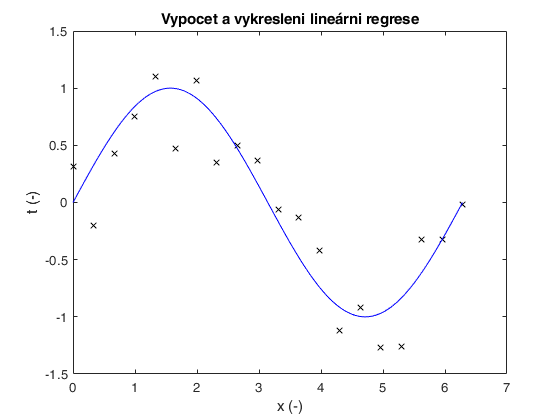

figure();
plot(x,t,'kx',x_c,t_c,'b');                     % vykreslení naměřených dat
title("Vypocet a vykresleni lineárni regrese");
xlabel("x (-)");
ylabel("t (-)")
hold on;

warning('off')                                  % zákaz vypisování warning zpráv

Dále do stejného grafu vykreslíme naší spočtenou aproximaci červeně, která je spočtena funkcí **Polynomial_regression. **Ta jako vstupní parametry přijmá trénovací vzorky, řád polynomu a následně regularizaci, která je zde ale nastavena na nulu, aby prozatím neovlivňovala řešení. Místo hodnoty M je zde použit slider pro nastavení libovolného řádu polynomu nula až dvacet.

% [t_w,~,~,~] = Polynomial_regression(x,t,3,0);   % výpočet aproximace pro M-tý řád polynomu
[t_w,~,~,~] = Gradient_descent_algorithm(x,t,M);

Requested array exceeds the maximum possible variable size.

Error in sym>createCharMatrixChecked (line 1646)
        s = cellfun(@(k)createCharMatrixElement(x,used,k),num2cell(1:total),'UniformOutput',false);

Error in sym>createCharMatrix (line 1600)
        s = createCharMatrixChecked(x,a);

Error in 

plot(x,t_w,'r--');                              % vykreslení proložení vypočítaným polynomem M
legend("Namerena trenovaci data","Puvodni krivka bez sumu", "Aproximacni krivka");